# V2 Process Plot and Save All AMC Files

This script performs an enhanced gait analysis on AMC files. It processes multiple AMC files, extracts gait cycles, filters the data, and generates various plots and saves processed data.

## Setup Environment

Clear workspace, close figures, and add necessary paths.

close all;
clc;
clear;

% Add necessary paths to access functions and data
addpath('./AMC/');
addpath('./Functions_rev/'); % Use the revised functions
addpath('./Gait Data/');

## Create Output Directories

This function creates the necessary output directories for saving plots and data.

create_output_directorie();

## Main Execution - Data Processing

Start the gait analysis process.

fprintf('\n=== Process Plot and Save All AMC Files Completed V2 ===\n');


=== Process Plot and Save All AMC Files Completed V2 ===



% Get all AMC files from the specified directory.
amc_files = get_amc_files();

Searching for AMC files in AMC folder...
Found 13 AMC files:
  1. 39_01.amc
  2. 39_02.amc
  3. 39_03.amc
  4. 39_04.amc
  5. 39_05.amc
  6. 39_06.amc
  7. 39_07.amc
  8. 39_08.amc
  9. 39_09.amc
  10. 39_10.amc
  11. 39_12.amc
  12. 39_13.amc
  13. 39_14.amc


% Process all AMC files to extract and collect gait cycle data.
[all_cycles_data, file_info] = process_all_amc_files_v2(amc_files, false, false);


=== PROCESSING ALL FILES (V2) ===
Processing file 1/13: 39_01.amc

=== SUMMARY STATISTICS ===
Total frames: 378
Duration: 3.14 seconds
Right Hip Flexion/Extension: Mean=10.97ï¿½, Range=[-22.57ï¿½, 34.12ï¿½]
Left Hip Flexion/Extension: Mean=11.08ï¿½, Range=[-24.87ï¿½, 32.38ï¿½]
Right Knee Flexion/Extension: Mean=39.72ï¿½, Range=[15.42ï¿½, 77.54ï¿½]
Left Knee Flexion/Extension: Mean=38.35ï¿½, Range=[9.66ï¿½, 74.84ï¿½]
  Found 2 right leg cycles and 2 left leg cycles
Processing file 2/13: 39_02.amc

=== SUMMARY STATISTICS ===
Total frames: 400
Duration: 3.33 seconds
Right Hip Flexion/Extension: Mean=10.50ï¿½, Range=[-21.82ï¿½, 31.69ï¿½]
Left Hip Flexion/Extension: Mean=11.63ï¿½, Range=[-23.01ï¿½, 34.63ï¿½]
Right Knee Flexion/Extension: Mean=40.06ï¿½, Range=[15.91ï¿½, 77.02ï¿½]
Left Knee Flexion/Extension: Mean=40.08ï¿½, Range=[7.12ï¿½, 76.20ï¿½]
  Found 2 right leg cycles and 2 left leg cycles
Processing file 3/13: 39_03.amc

=== SUMMARY STATISTICS ===
Total frames: 407
Duration: 3.38 se


% Apply filtering to the collected gait data and calculate derivatives.
processed_data = apply_filtering_and_derivatives_v2(all_cycles_data);


=== APPLYING FILTERING AND DERIVATIVES (V2) ===
Filter parameters:
  Sampling frequency: 199.0 Hz
  Cutoff frequency: 6.00 Hz
  Processing 25 cycles for right_leg_cycles...
  Processing 27 cycles for left_leg_cycles...
Filtering and derivative calculation complete!



=== PLOTTING GAIT KINEMATICS (V2) ===
  Plotting Right Leg Cycles...


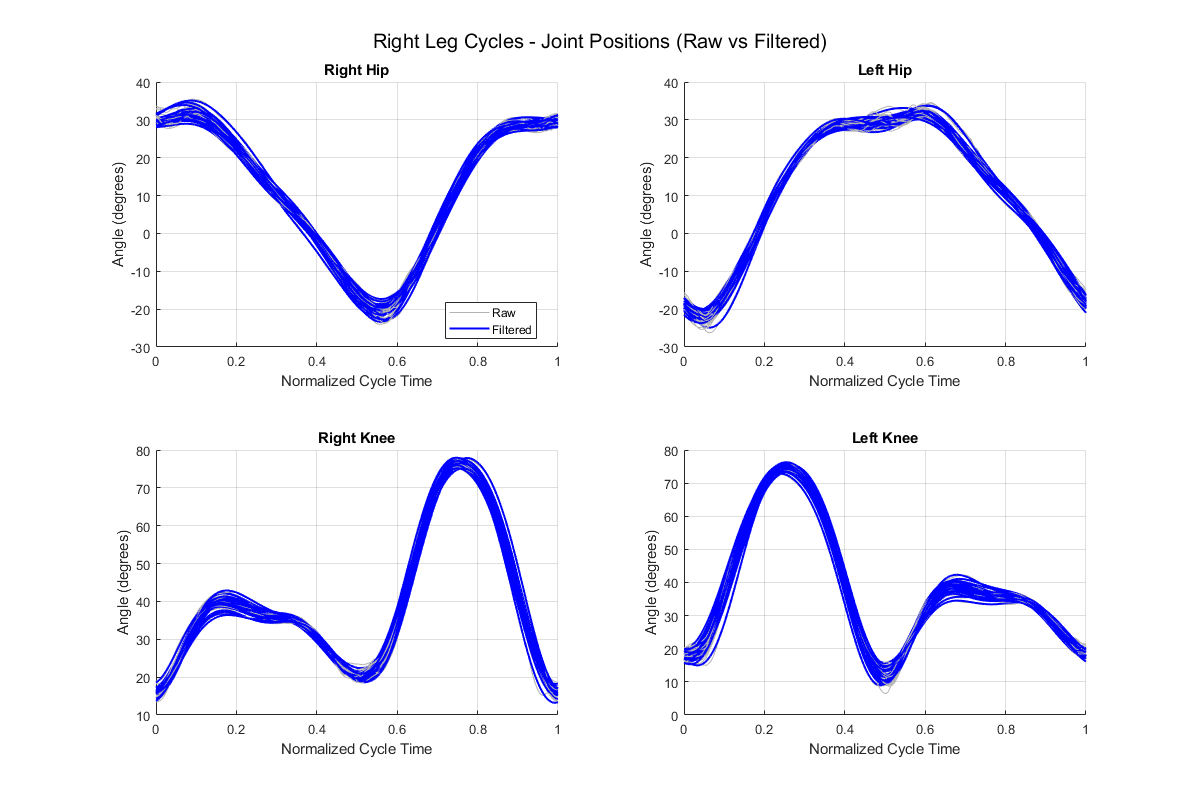

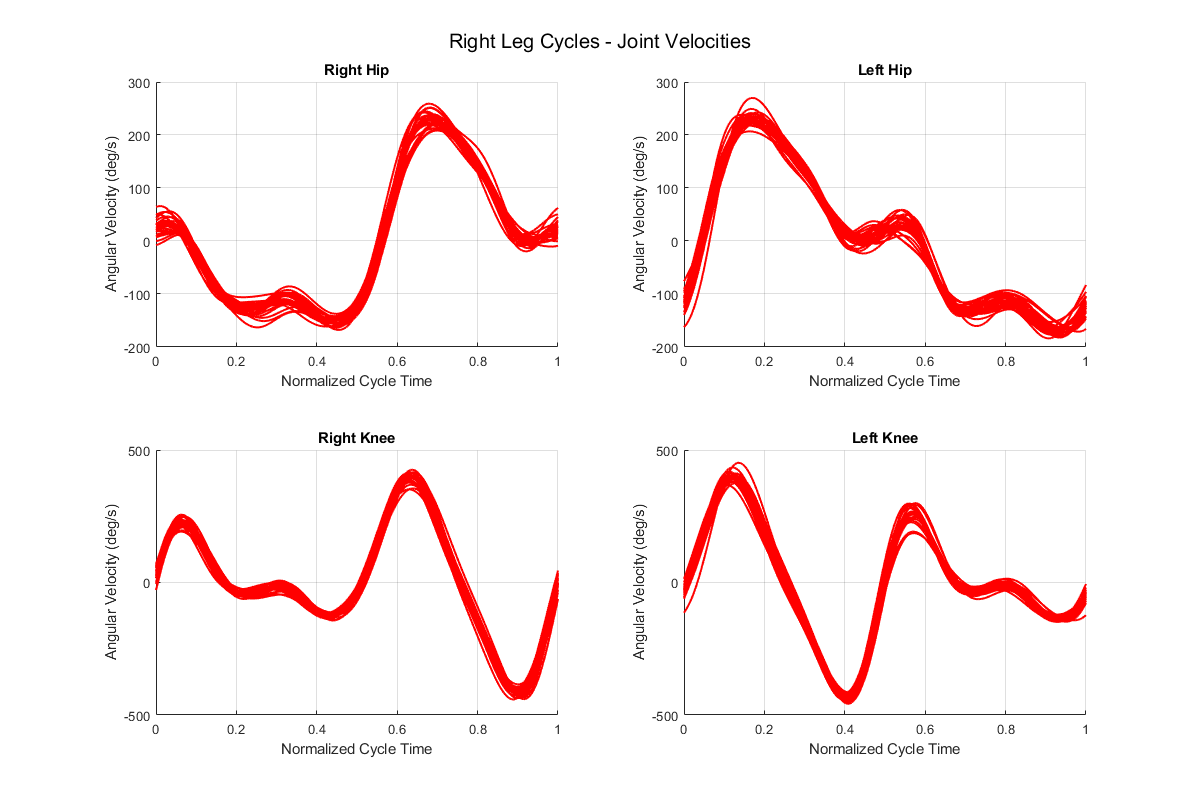

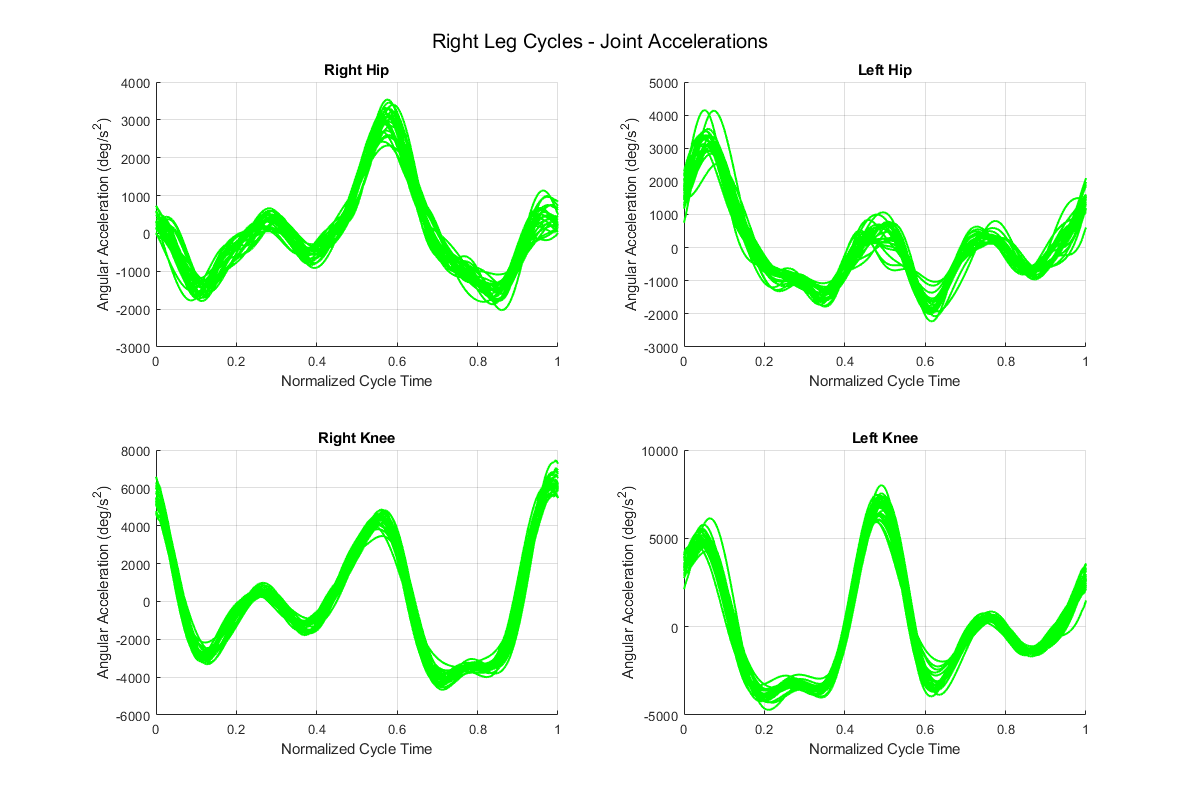

  No left leg cycles to plot or plotting skipped.
Plotting complete!



plot_gait_kinematics_v2(processed_data, 'right');


=== PLOTTING GAIT KINEMATICS (V2) ===
  No right leg cycles to plot or plotting skipped.
  Plotting Left Leg Cycles...


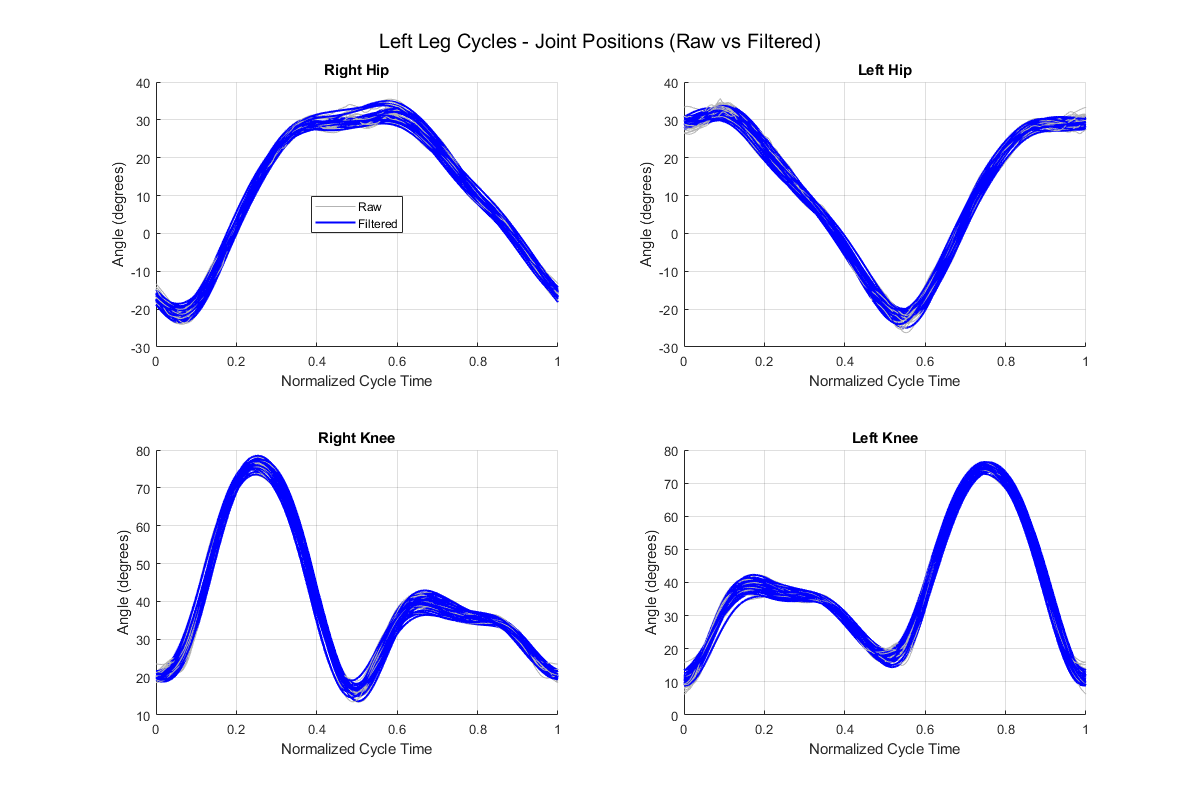

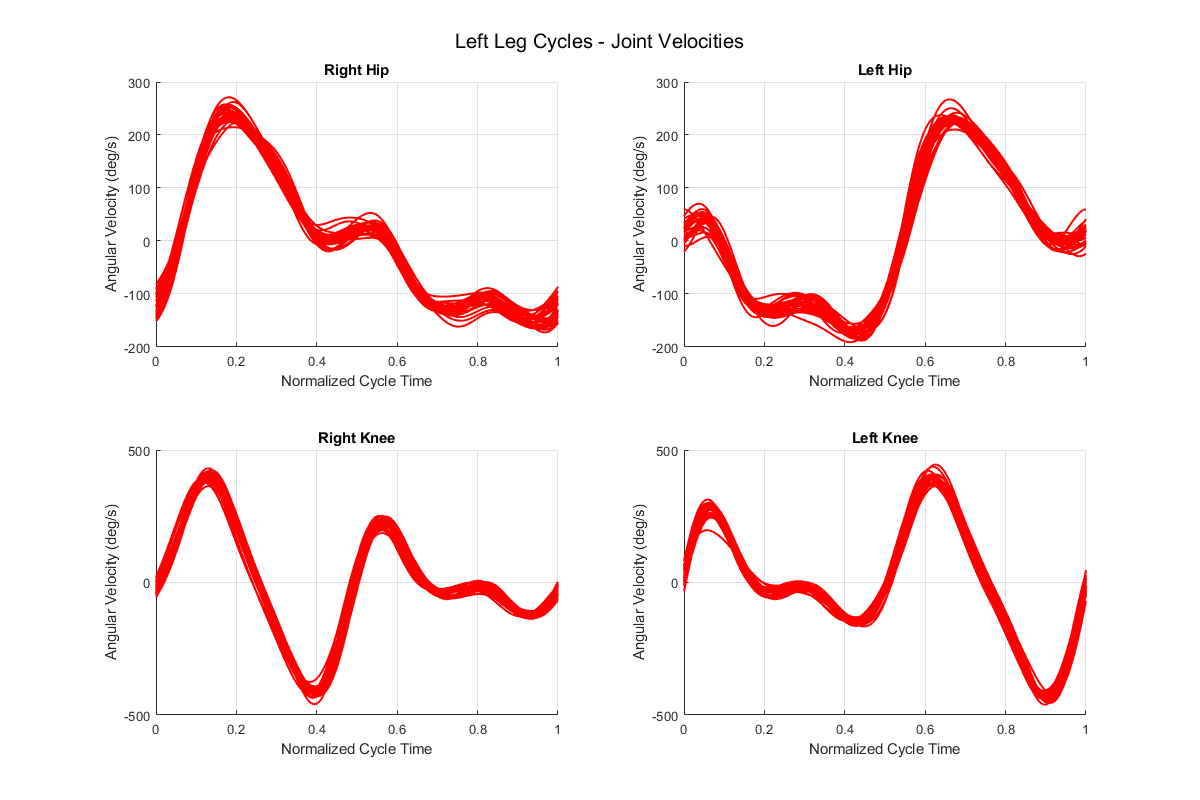

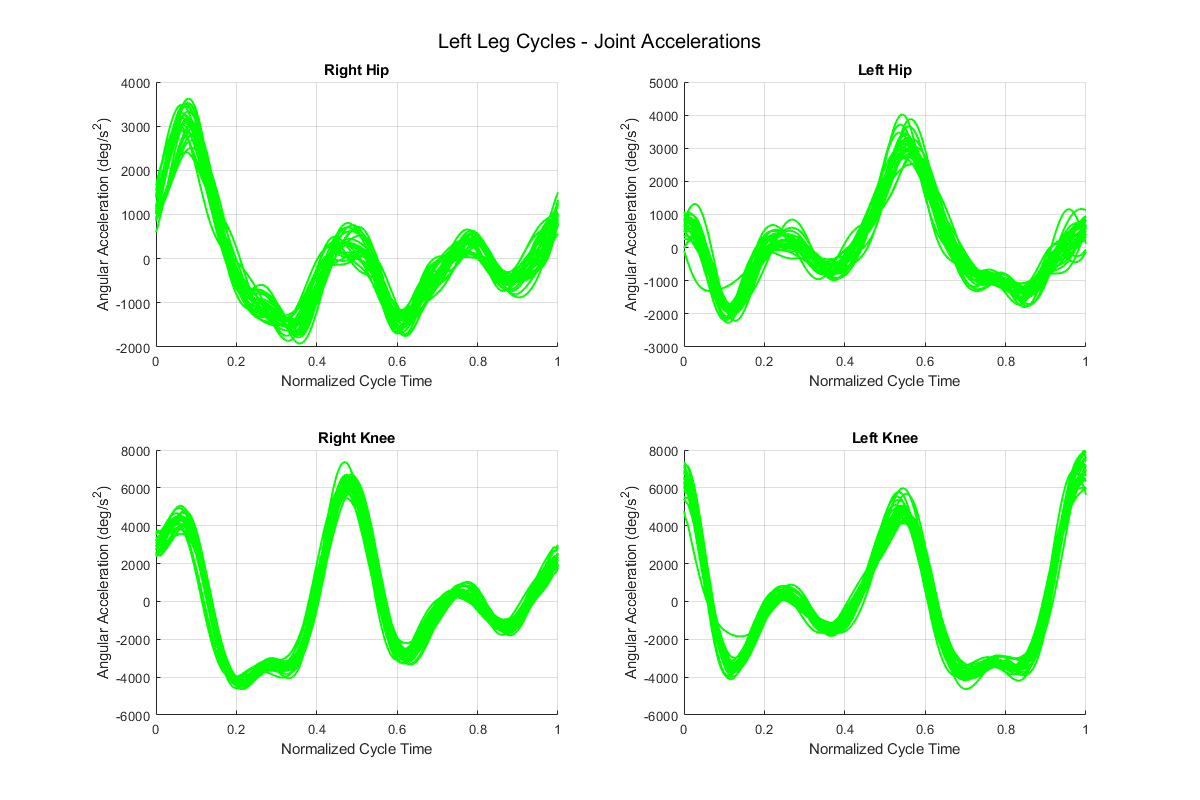

Plotting complete!


plot_gait_kinematics_v2(processed_data, 'left');

% Save the processed data in multiple formats for further analysis.
% save_processed_data(processed_data, file_info, 10);
save_processed_data_4D(processed_data);


=== SAVING PROCESSED DATA (4D) ===
  Processing 25 of 25 right leg cycles for saving...
  Saved right leg data to Gait Data\processed_data_right_leg_4D.mat
  Processing 27 of 27 left leg cycles for saving...
  Saved left leg data to Gait Data\processed_data_left_leg_4D.mat
Saving complete!




% Reshape the processed data for further analysis and plotting.
% reshaped_data = reshapeProcessedData(processed_data);

% Plot the joint cycles from the reshaped data.
% plot_joint_cycles(reshaped_data);

## Plotting - Trajectories and Phase Plots

Generate various plots to visualize the gait data.

% % Create and save trajectory plots for the unfiltered (original) data.
% create_trajectory_plots(processed_data, file_info, false);
% 
% % Create and save trajectory plots for the filtered data.
% create_filtered_trajectory_plots(processed_data, file_info, false);
% 
% % Create and save phase plots for the processed data.
% create_phase_plots(processed_data, file_info, false);

## Kinematics Calculation and Plotting

Calculate and visualize linear kinematics.

% % Create a 'Data' structure, where each cell represents a single gait cycle.
% Data_filteredv2 = create_demos_structure_per_cycleV2(processed_data);
% 
% % Plot the angular kinematics positions.
% plot_angular_kinematics_positions(Data_filteredv2, false);
% 
% % Reshape the filtered data to separate left and right leg data for linear kinematics.
% reshaped_filtered_data = reshape_leg_data(Data_filteredv2);
% 
% % Calculate linear kinematics from the filtered 'Data' structure.
% % The -90 degree rotation is applied here.
% linear_kinematics = calculate_linear_kinematics(reshaped_filtered_data, -90);
% 
% % Save the calculated linear kinematics of the gait cycles.
% save_linear_kinematics(linear_kinematics, 50);
% 
% % Create a 'Data' like structure for the linear kinematics.
% Data_linear = create_linear_kinematics_structure(linear_kinematics);
% 
% % Plot the linear kinematics positions, velocities, and accelerations.
% plot_linear_kinematics_positions(linear_kinematics, processed_data, false);
% 
% % Save the structured linear kinematics data.
% % Note: 'struct_kinematrics' function is not provided in the context, assuming it exists.
% structData = struct_kinematrics(linear_kinematics, size(linear_kinematics, 2));
% save_linear_kinematics_structured(structData, 10);
% 
% fprintf('\n=== Process Plot and Save All AMC Files Completed V2 ===\n');